# Plot Bootcamp

## Anatomy of the plot

Most plots suprsingly are composed of only a few basic elements. We're not dealing in hundreds but maybe only 10s of fundamental piecces. The rest can be learned on the job.

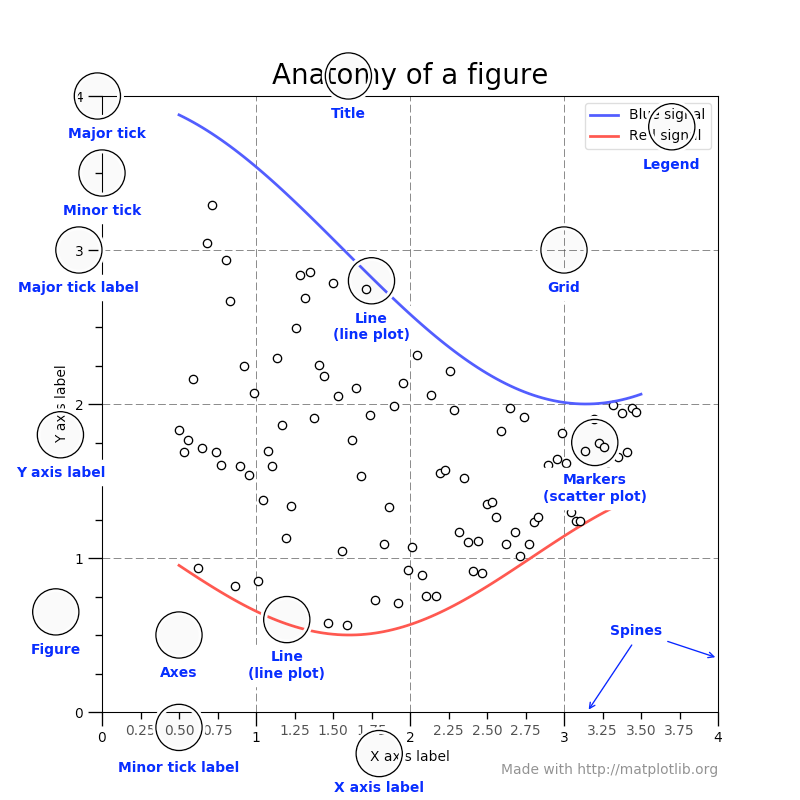

Everything inside the boxed region defined by the x-y axis spines (top spine, bottom spine, left spine, right spine) we will refer to as the ***canvas (inner-elements)***. And everhthing outside we will refer to as ***outer-elements*****.**

### Outer-elements : everything outside what happens in a canvas

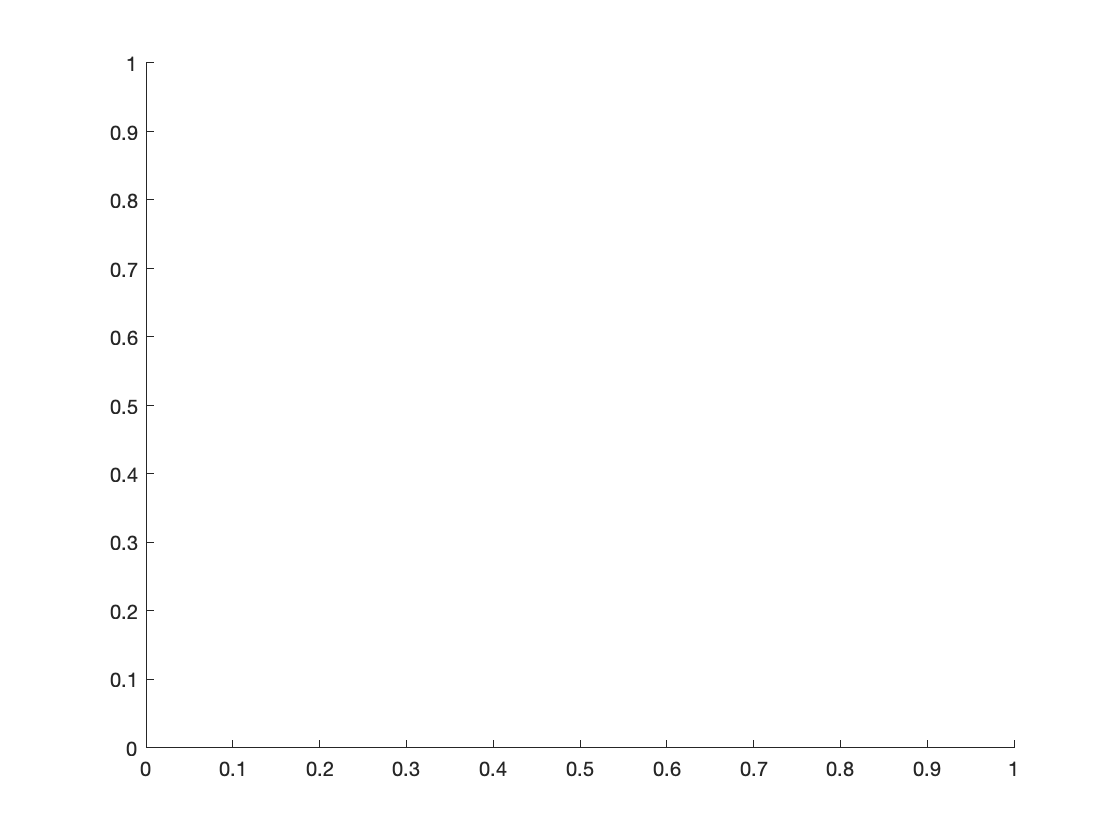

figure;
axes % axes

An axis alone contains the axes, the markers and labels on the axes, and the title. It has a blank canvas to store drawn objects like lines and shapes. Nothing else. By default if you call `figure`; and then immediatley issue `plot / area / bar / rectangle / etc c`ommands, it will automatically make an axis object on that figure.

Figure objects contain axes. They're a container for axes with very limited properties saying their total dimension and background color. All axis objects have a canvas surrounded by these boundary elements (x-axes/y-axes/etc). 

You can make a collection of axis objects in figure by cutting it up grid-wise with subplot.

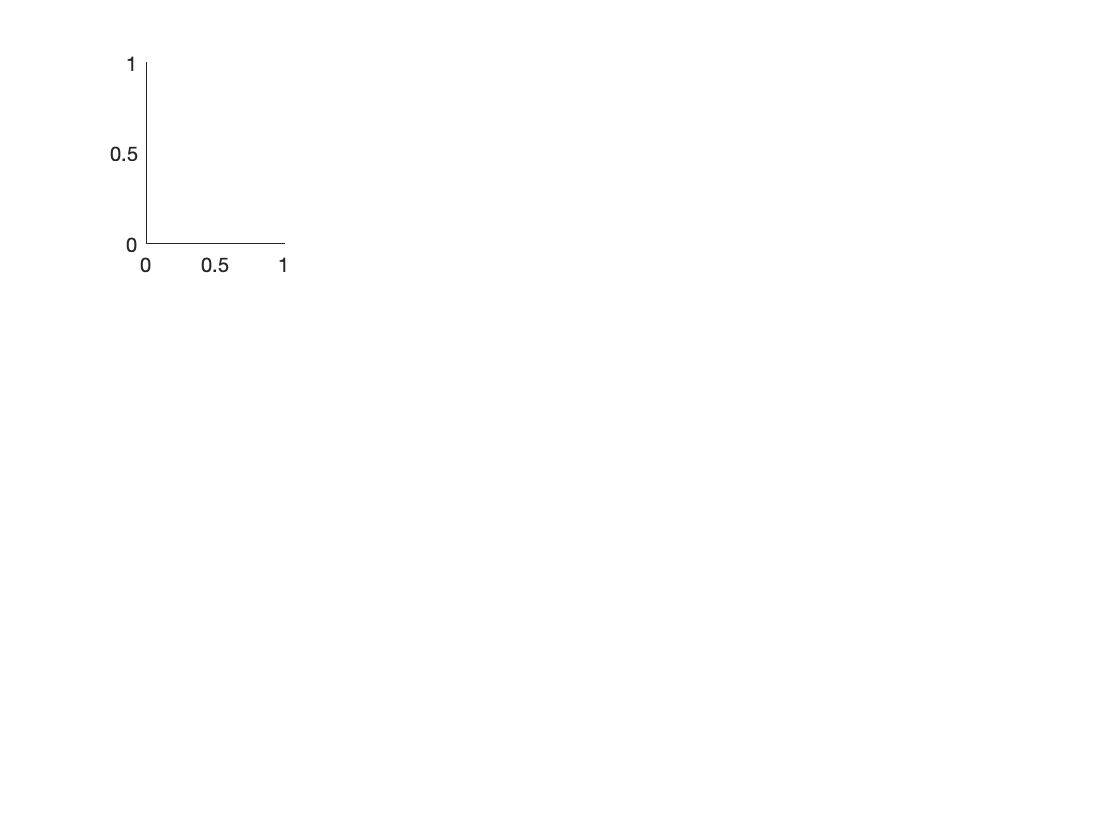

figure;
ax1 = subplot(3,5,1);

If you didn't make a variable for fig or axis, then use gca or gcf to get them for the most recent figure or axes

ax = gca

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.1237 0.2157]
            Units: 'normalized'

  Show all properties


same for figure

fig = gcf

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [560 528 560 420]
       Units: 'pixels'

  Show all properties


When I do that it places an axis object at the 1st location of a 3x5 grid in the figure, and automatically makes an axis object `ax1, `which refers to it. And if we were to for loop the last argument of `subplot(3,5,iAx)`, then you could see that it will make axes for all the locations on the 3x5 grid of the figure (an axis collection object).

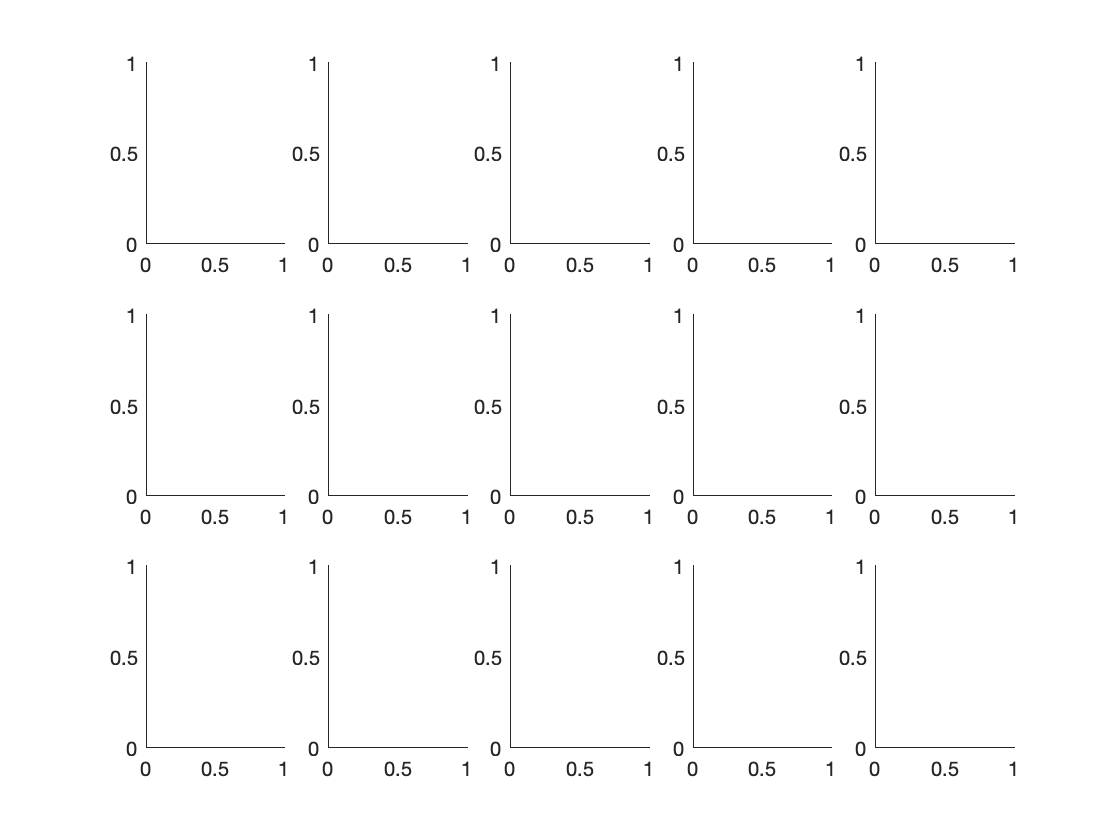

fig=figure;
for iAx = 1:(3*5)
subplot(3,5,iAx);
end

Figure is a collection of axes objects. Every graphical object who has a collection of things, that collection will be called `Children`. And you can access that,

children = fig.Children

children =   15×1 Axes array:

  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes
  Axes


you'll see children is an array of Axes

class(children)

ans = 'matlab.graphics.axis.Axes'

## Canvass elements

All canvass elements have optional arguments when you create them that control everything from color to shade/transparency to font style.

### Types of plots

#### Lines

line() : straight lines

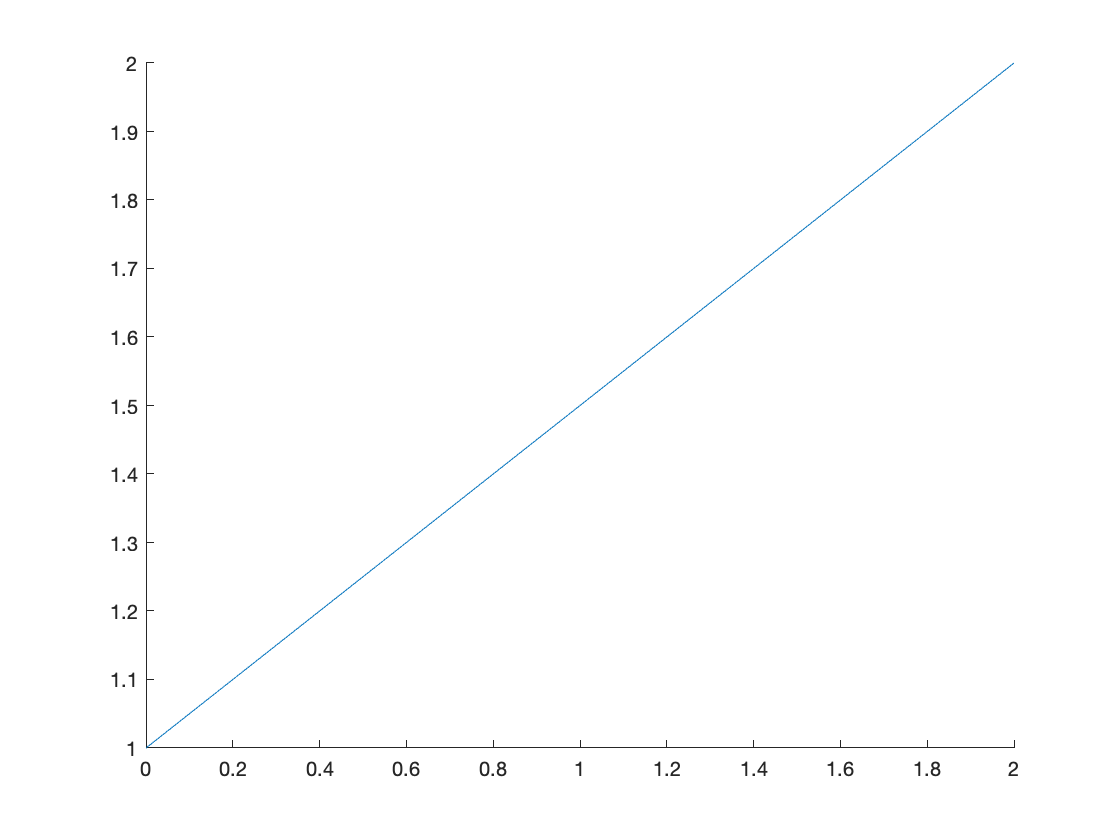

figure;
line([0,2], [1,2])

plot() : make a curve

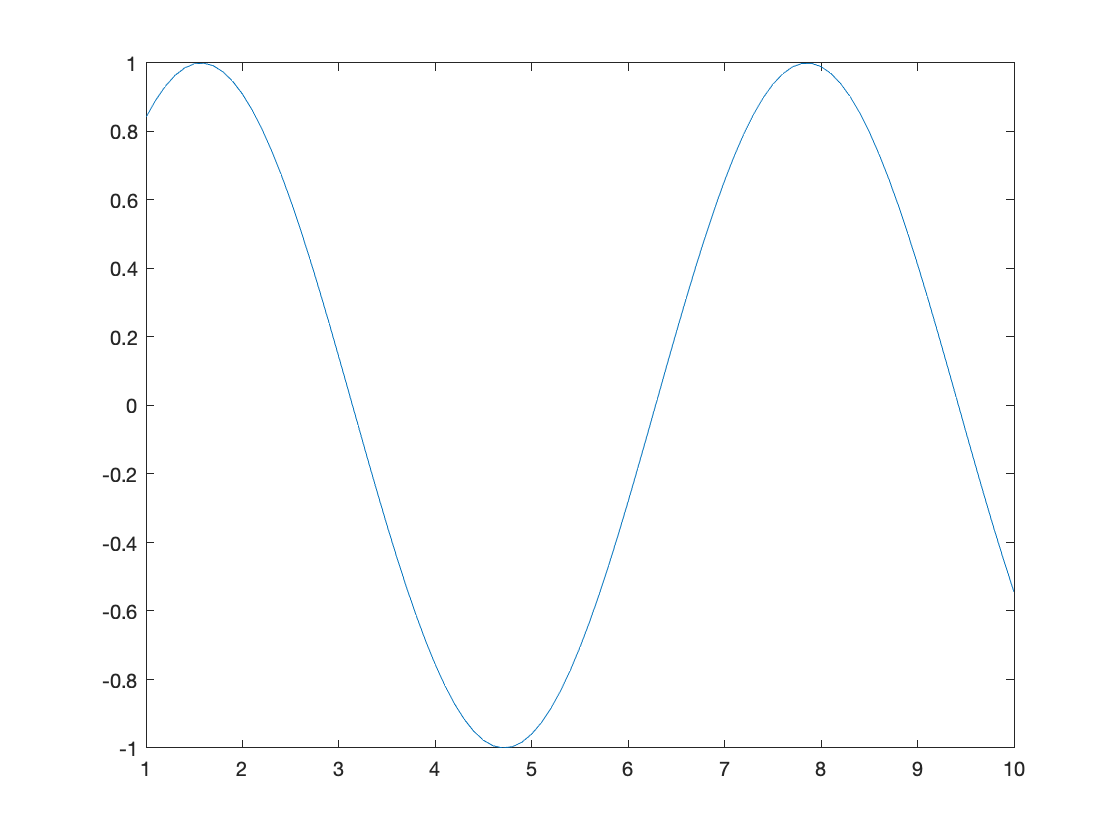

plot(1:0.1:10, sin(1:0.1:10))

area() : shade under a curve

area(1:0.1:10, sin(1:0.1:10))

Whenever you drop a canvas element, by default it overwrites previous canvas elements. Unless, a property called `hold` is `on`.

Which you can also make toggle keyword-value properties of any these objects. These will always be found in the reference document for the function. Usually these are the color of the area, the color of the edge bounding the area, the color of a line, transparency of any of those, text size/style, line style, et cetera.

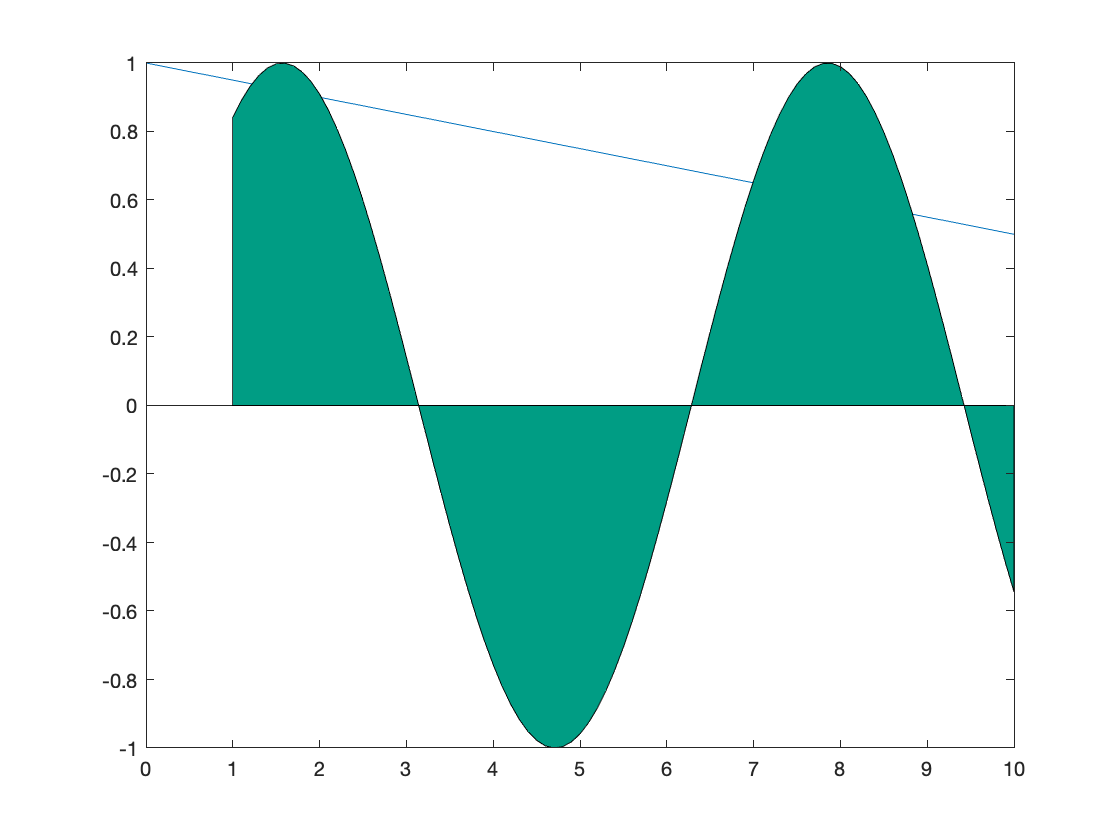

hold off % off means, everything overwritten by the next canvas operation, which is line
line([0,10],[1,1/2])
hold on; % hold on means don't overwrite canvas
area(1:0.1:10, sin(1:0.1:10), 'FaceColor','green','FaceAlpha',0.3)
hold off;

#### Shaded boxes/areas

box() : bar graph style graphics

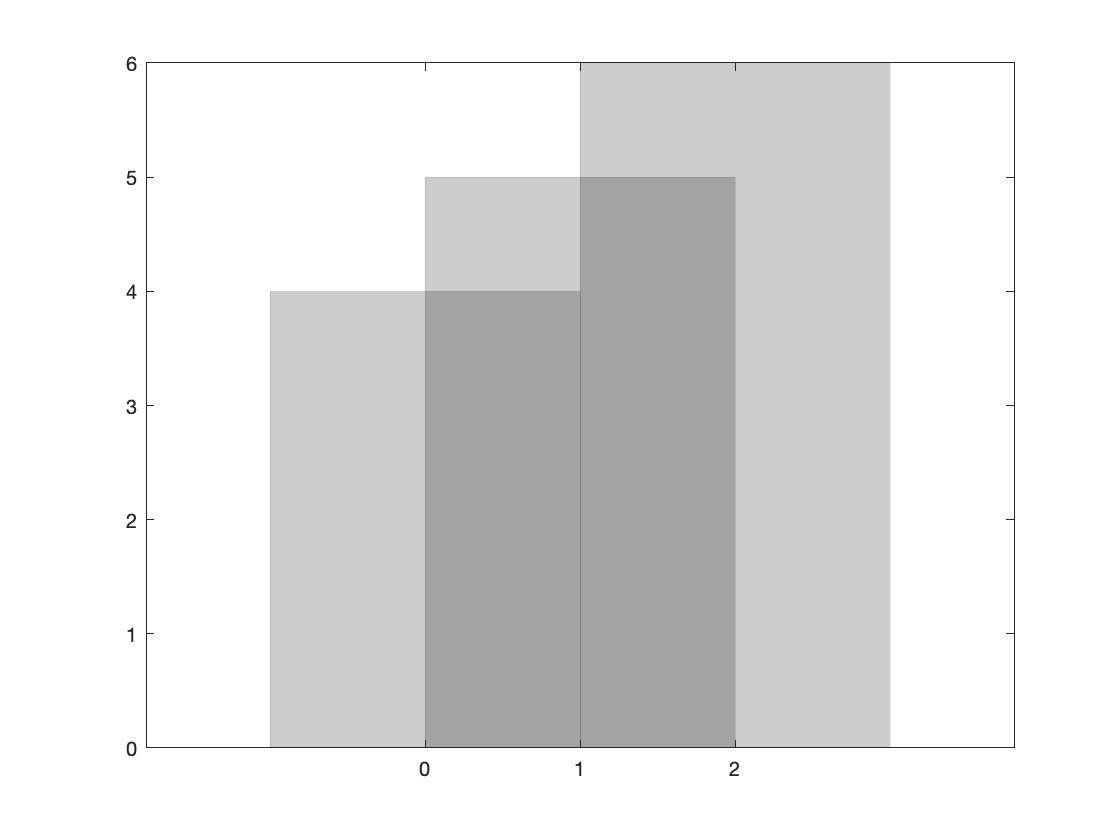

figure
bar([0 1 2], [4 5 6], 2, "grouped", 'black', 'FaceAlpha',0.2, 'EdgeAlpha',0.1)

rectangle() : draw a rectangle anywhere

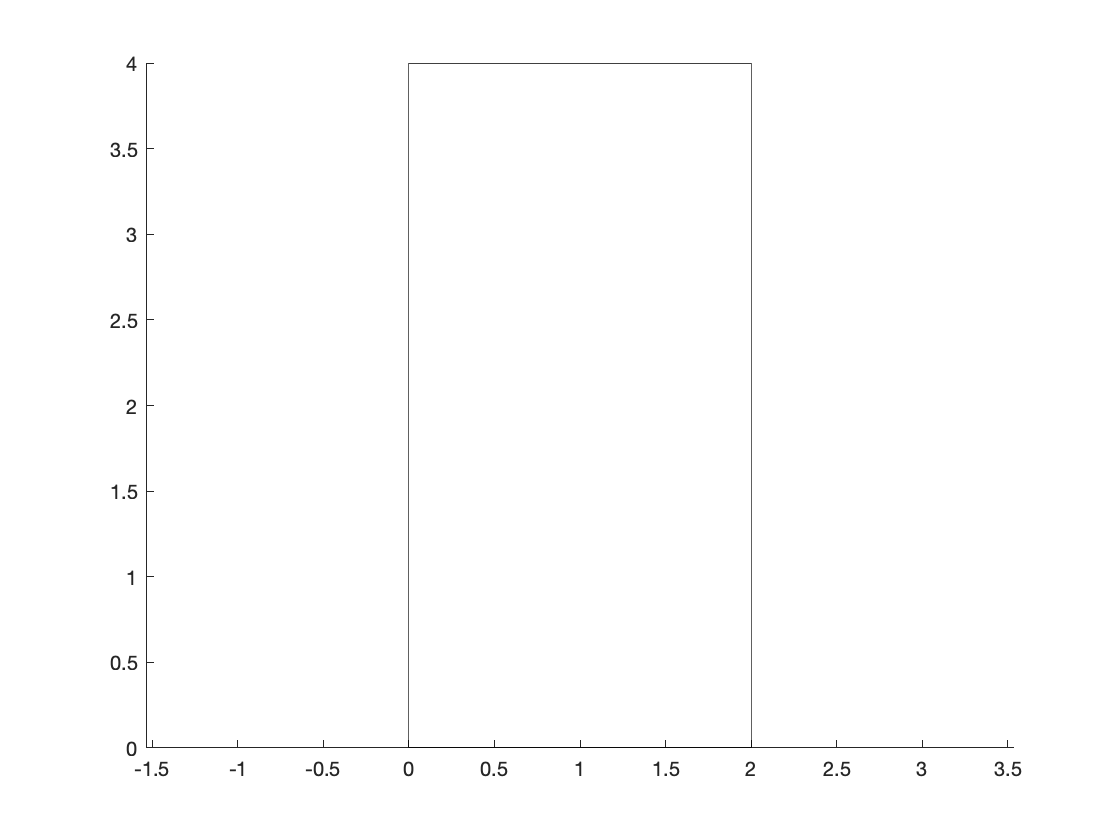

figure
rectangle('Position',[0 0 2 4])
axis equal

%axis equal % makes the x and y axis the same length

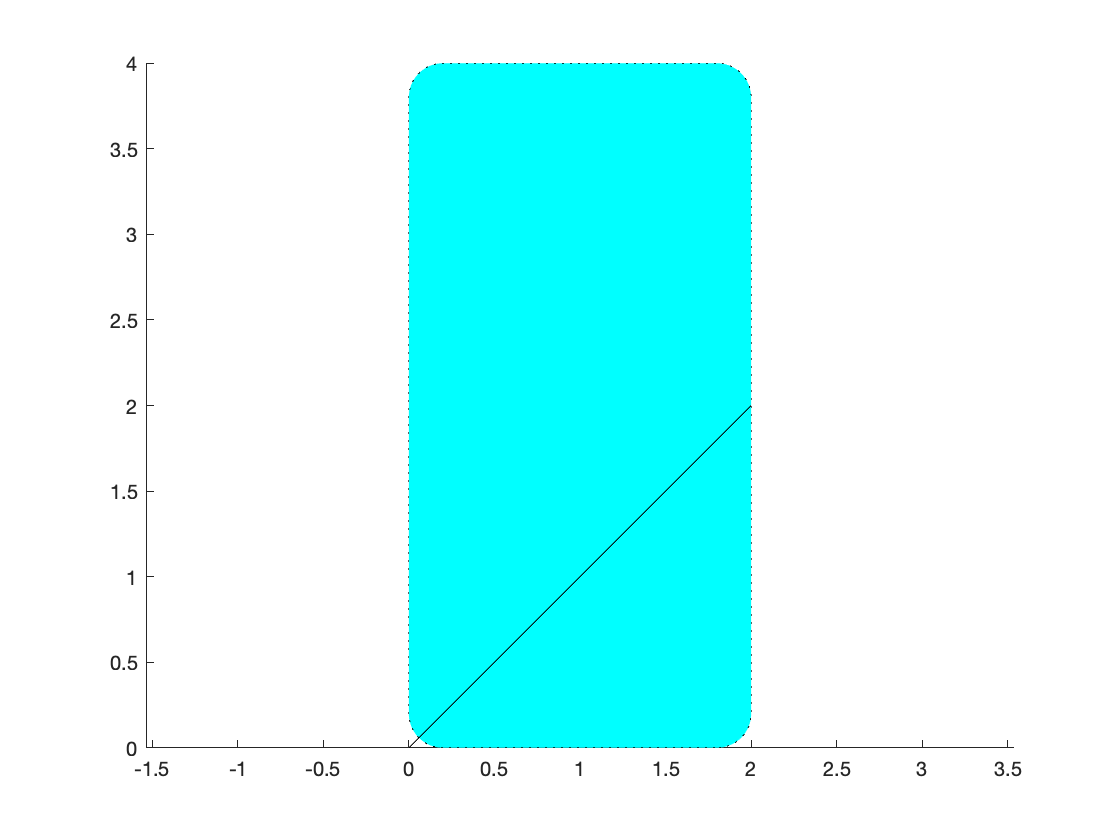

figure
rectangle('Position',[0 0 2 4],'Curvature',0.2, 'LineStyle',':', 'FaceColor',[0,1,1,0.1])
hold on;
line([0 2], [0 2],'Color','black')
axis equal % makes the x and y axis the same length

text() : allows you to add text anywhere in the canvas

text(1,2,'Hello world!')

Keyword-value pairs can change every possible property of text

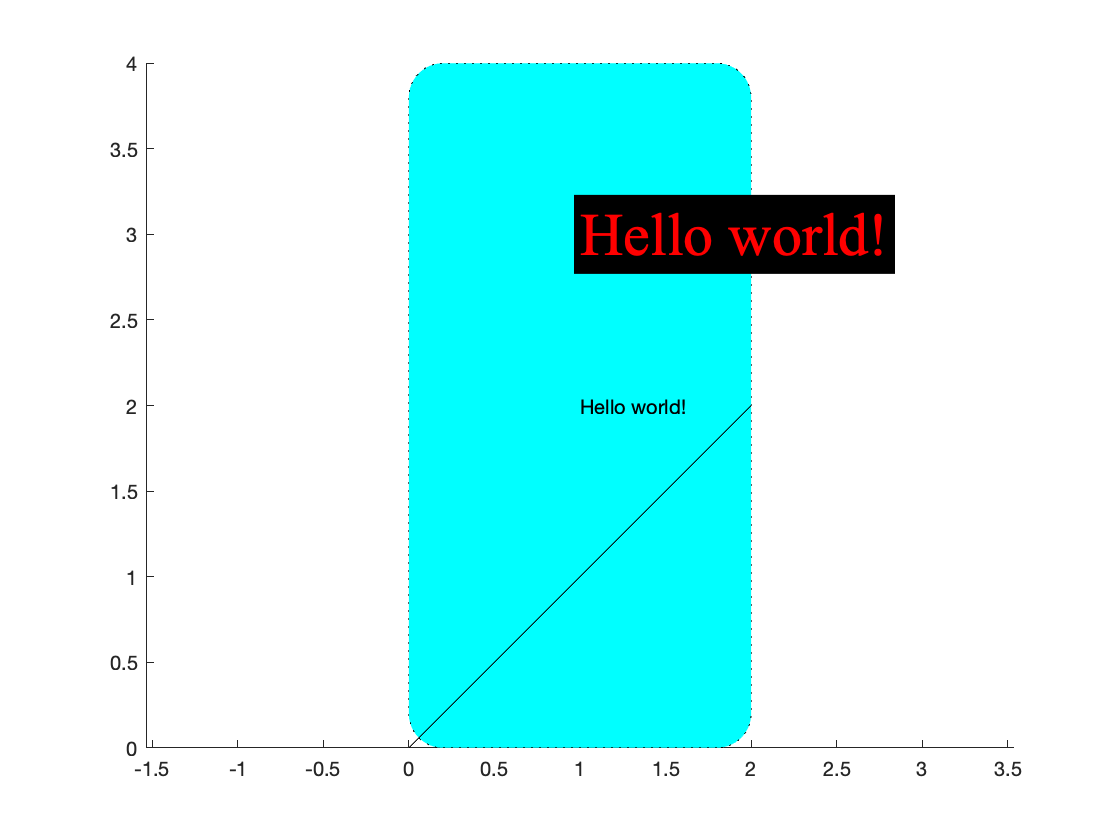

text(1,3,'Hello world!','FontSize',30, 'FontName','Times New Roman', 'Color','Red', 'BackgroundColor', 'black')

####  Image/Matrix

image()  : plot image data (e.g. a matrix, as if it were an image)

Basically takes either values a 2D matrix of values from 0 to 1 at every (x,y) coordinate or a 3D matrix of RGB values at each (x,y) coordinate.

nebula = imread('ngc6543a.jpg') % read in a jpg image of a nebula

nebula = 650×600×3 uint8 array
nebula(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

[xpixels, ypixels, rgbDimension] = size(nebula)

xpixels = 650

ypixels = 600

rgbDimension = 3

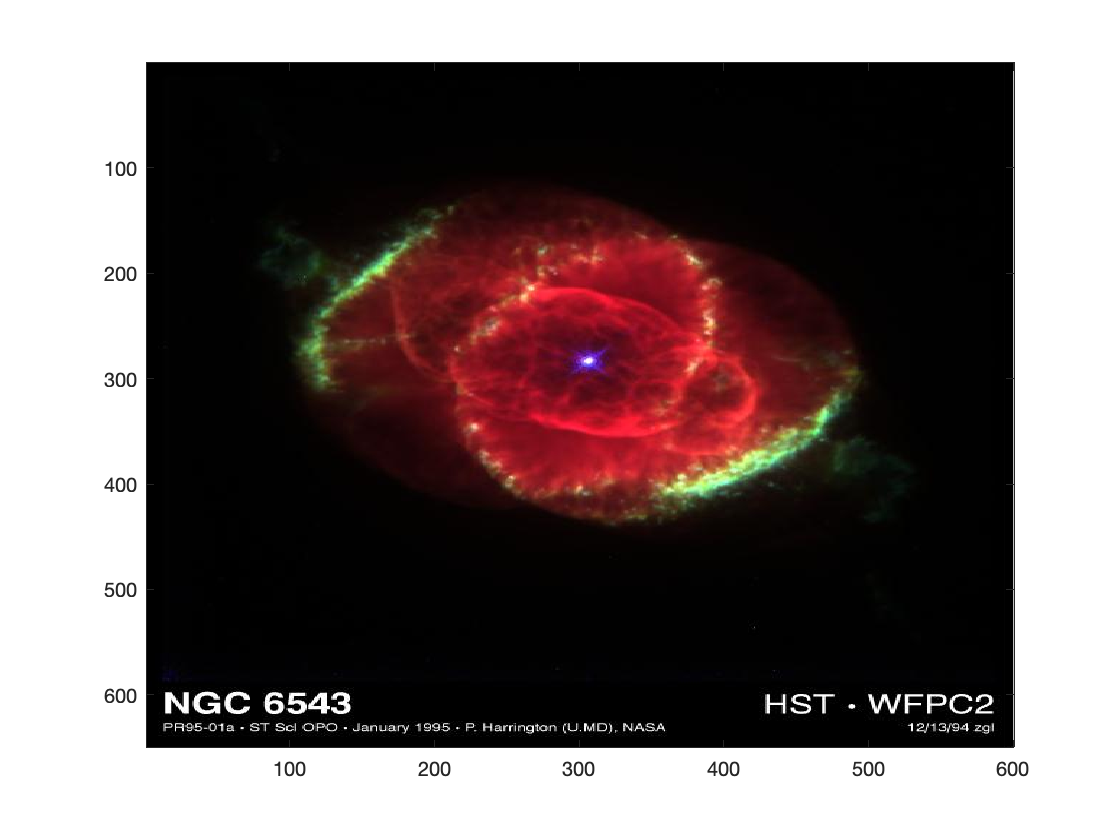

figure;
image(nebula)

nebula(1,1,:)

ans = 1×1×3 uint8 array
ans(:,:,1) =

   0


ans(:,:,2) =

   0


ans(:,:,3) =

   0


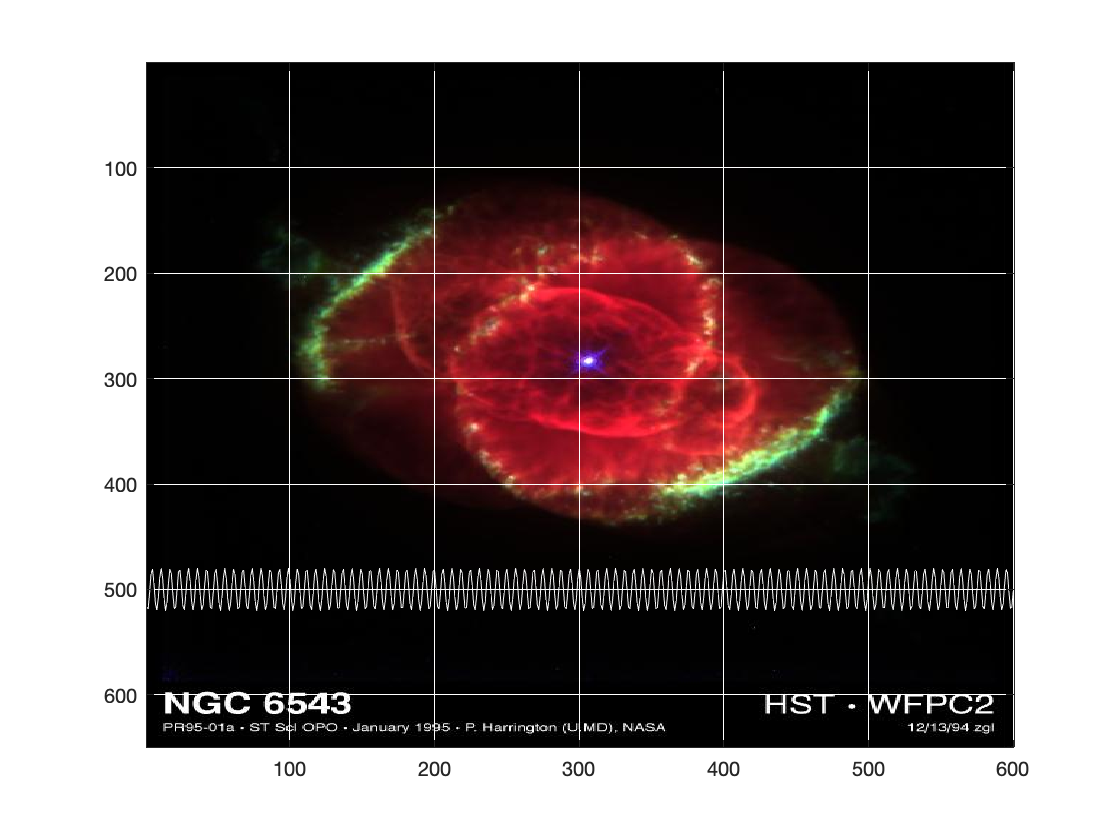

grid on
ax=gca;
set(ax,'GridAlpha',1,'GridColor','white')
hold on
plot(1:xpixels, 500 + 20*sin(1:xpixels),'Color','white','LineWidth',0.5)

imagesc() : plot image *SCALED*

What this does is plots image data, but scales the colormap internally to match the value range of the data. Meaning if say you're  using a `parula` colormap, then your lowest to highest value will cover the following colors:

So if I get a random matrix to represent pixels, values from 0 to a million,

matrix = 1e6 * randn(100) % draw from a normal distribution, and use mult. to scale to a million

matrix = 	1.0e+06 *

   -1.3077   -0.6003    0.5152   -0.6912    0.1097    0.4400   -0.5097    0.6901    0.4120   -1.0368   -0.7781    0.2053   -0.6187   -0.3038    0.4488   -0.5279    0.2918   -0.1379   -0.5040   -0.6563    0.7337    0.9923    2.4304    0.4784    0.1534   -0.1972    2.0183   -0.2503   -1.7729    0.2403   -0.6986   -0.8901   -0.8933    0.6476   -0.6199   -1.2898   -0.6728    0.8294    1.2334    0.3717    0.2332   -0.3672   -0.3887    0.3404   -0.0061    1.4148   -1.2981   -1.3227   -1.3012   -1.1843
   -0.4336    0.4900    0.2614    0.4494    1.1287    0.1017   -0.0029    0.5558    0.4055   -0.8571   -1.0636    1.1929    0.9345   -0.0087    0.0006    0.7231   -0.6146    0.6199   -1.2240   -0.1250    0.1203    0.5762   -0.4715   -1.0411   -0.3170   -0.1464    0.4543   -1.6488   -0.0725   -1.0462   -1.4236    0.9107    1.1221    2.0541   -1.0246   -0.3998   -0.5370    0.1556   -0.7576    0.1917    2.1013   -2.3638   -0.3119   -1.5921    1.8663   -0.4841    1.0717   -0.67

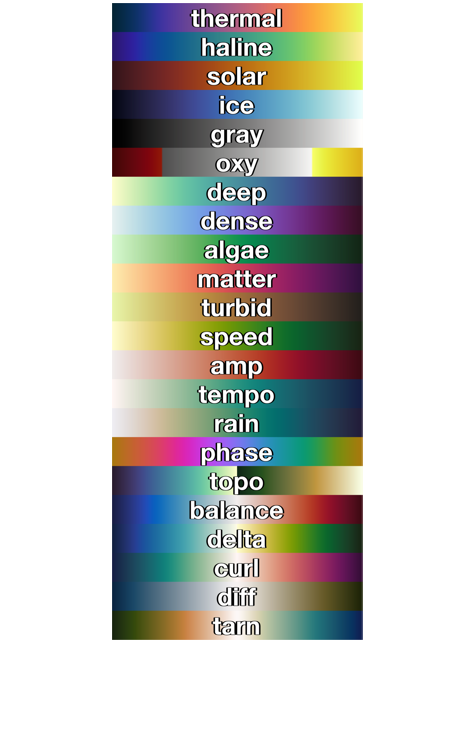

addpath('Shared/cmocean')
cmocean()

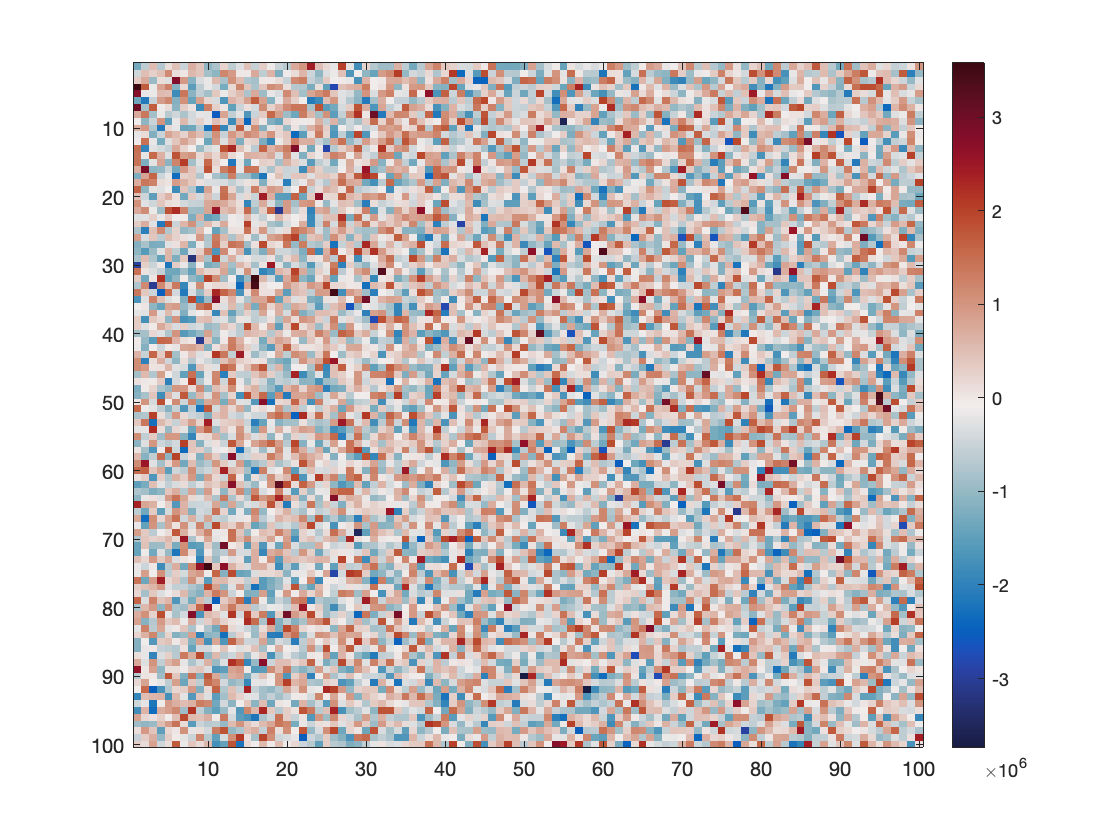

figure
imagesc(matrix);
cmocean('balance')
colorbar

pcolor() : pseudo color

It basically is a more flexible version of `image` / `imagesc` . you can plot image-like data on non-grid coordinate systems, e.g.

And

figure;
[X,Y] = meshgrid(-3:6/17:3)

X =    -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765    0.1765    0.5294    0.8824    1.2353    1.5882    1.9412    2.2941    2.6471    3.0000
   -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765    0.1765    0.5294    0.8824    1.2353    1.5882    1.9412    2.2941    2.6471    3.0000
   -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765    0.1765    0.5294    0.8824    1.2353    1.5882    1.9412    2.2941    2.6471    3.0000
   -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765    0.1765    0.5294    0.8824    1.2353    1.5882    1.9412    2.2941    2.6471    3.0000
   -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765    0.1765    0.5294    0.8824    1.2353    1.5882    1.9412    2.2941    2.6471    3.0000
   -3.0000   -2.6471   -2.2941   -1.9412   -1.5882   -1.2353   -0.8824   -0.5294   -0.1765 

Y =    -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000
   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471   -2.6471
   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941   -2.2941
   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412   -1.9412
   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882   -1.5882
   -1.2353   -1.2353   -1.2353   -1.2353   -1.2353   -1.2353   -1.2353   -1.2353   -1.2353 

XX = 2*X.*Y

XX =    18.0000   15.8824   13.7647   11.6471    9.5294    7.4118    5.2941    3.1765    1.0588   -1.0588   -3.1765   -5.2941   -7.4118   -9.5294  -11.6471  -13.7647  -15.8824  -18.0000
   15.8824   14.0138   12.1453   10.2768    8.4083    6.5398    4.6713    2.8028    0.9343   -0.9343   -2.8028   -4.6713   -6.5398   -8.4083  -10.2768  -12.1453  -14.0138  -15.8824
   13.7647   12.1453   10.5260    8.9066    7.2872    5.6678    4.0484    2.4291    0.8097   -0.8097   -2.4291   -4.0484   -5.6678   -7.2872   -8.9066  -10.5260  -12.1453  -13.7647
   11.6471   10.2768    8.9066    7.5363    6.1661    4.7958    3.4256    2.0554    0.6851   -0.6851   -2.0554   -3.4256   -4.7958   -6.1661   -7.5363   -8.9066  -10.2768  -11.6471
    9.5294    8.4083    7.2872    6.1661    5.0450    3.9239    2.8028    1.6817    0.5606   -0.5606   -1.6817   -2.8028   -3.9239   -5.0450   -6.1661   -7.2872   -8.4083   -9.5294
    7.4118    6.5398    5.6678    4.7958    3.9239    3.0519    2.1799    1.3080    0.4360

YY = X.^2 - Y.^2

YY =          0   -1.9931   -3.7370   -5.2318   -6.4775   -7.4740   -8.2215   -8.7197   -8.9689   -8.9689   -8.7197   -8.2215   -7.4740   -6.4775   -5.2318   -3.7370   -1.9931         0
    1.9931         0   -1.7439   -3.2388   -4.4844   -5.4810   -6.2284   -6.7266   -6.9758   -6.9758   -6.7266   -6.2284   -5.4810   -4.4844   -3.2388   -1.7439         0    1.9931
    3.7370    1.7439         0   -1.4948   -2.7405   -3.7370   -4.4844   -4.9827   -5.2318   -5.2318   -4.9827   -4.4844   -3.7370   -2.7405   -1.4948         0    1.7439    3.7370
    5.2318    3.2388    1.4948         0   -1.2457   -2.2422   -2.9896   -3.4879   -3.7370   -3.7370   -3.4879   -2.9896   -2.2422   -1.2457         0    1.4948    3.2388    5.2318
    6.4775    4.4844    2.7405    1.2457         0   -0.9965   -1.7439   -2.2422   -2.4913   -2.4913   -2.2422   -1.7439   -0.9965         0    1.2457    2.7405    4.4844    6.4775
    7.4740    5.4810    3.7370    2.2422    0.9965         0   -0.7474   -1.2457   -1.4948

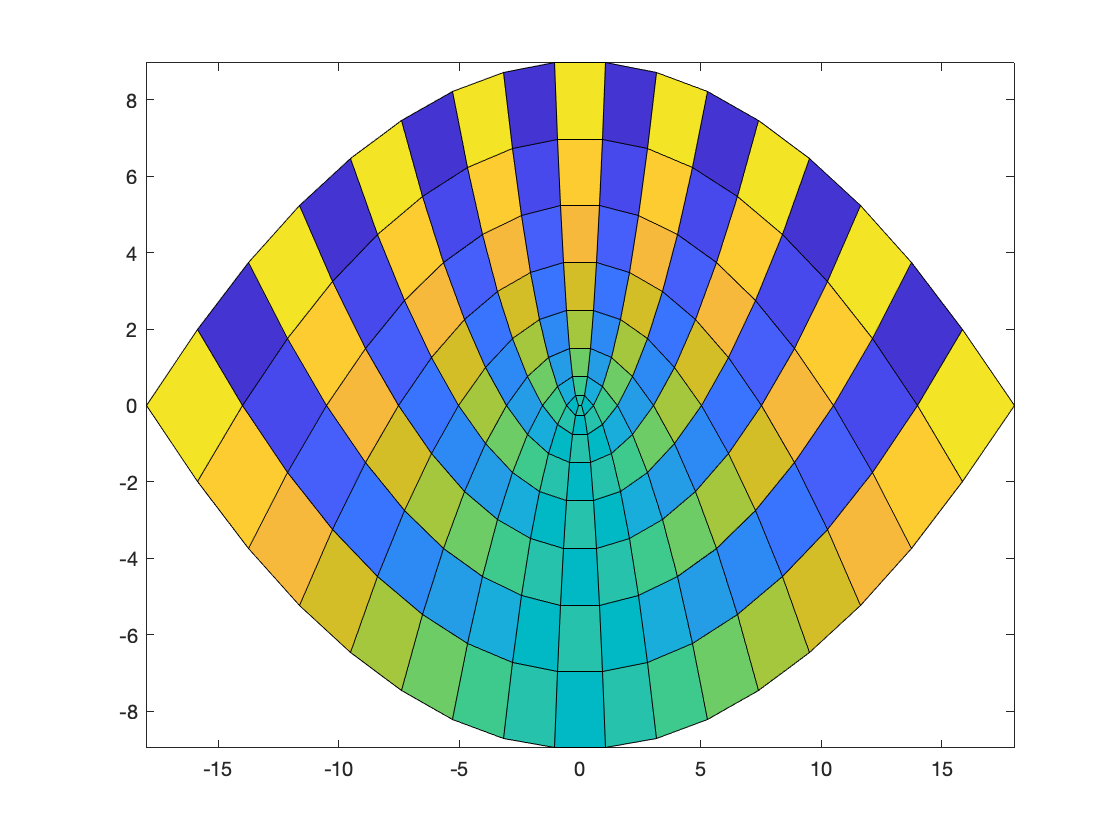

colorscale = [1:18; 18:-1:1];
C = repmat(colorscale,9,1);
pcolor(XX,YY,C); % pinning values in C (who have colors for values) to XX (x locations) and YY (y locations)

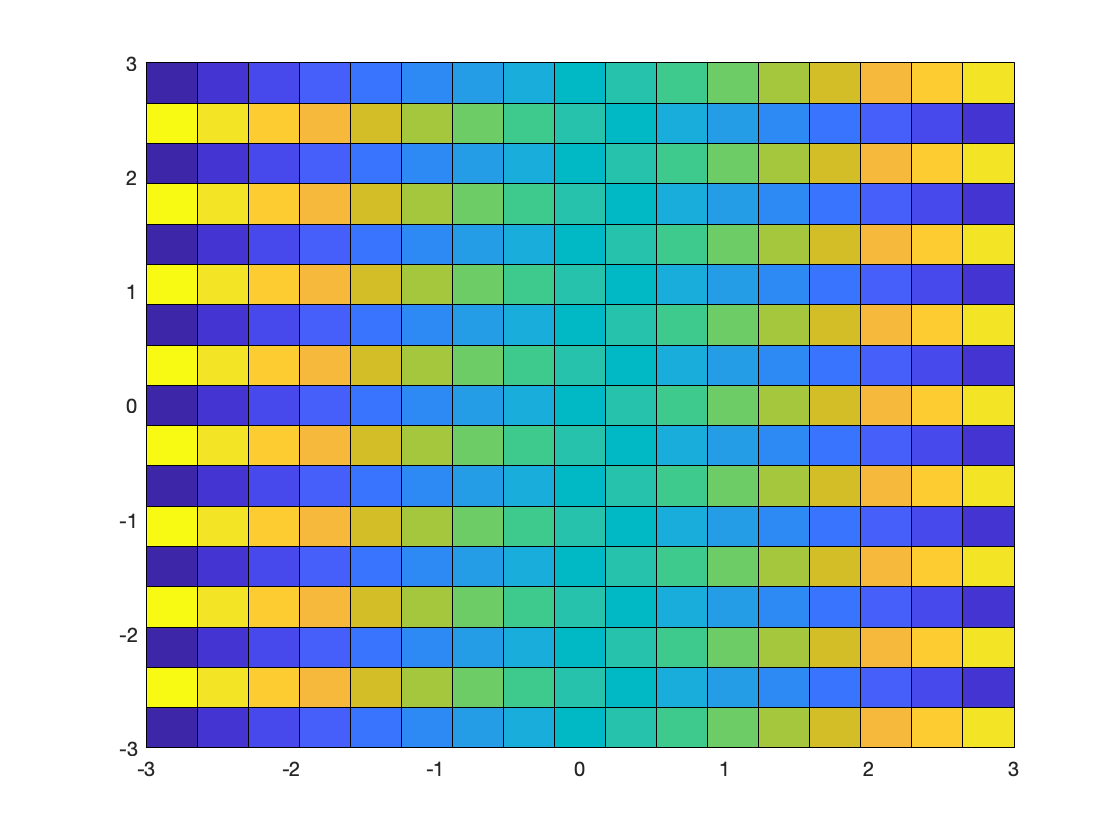

figure
colorscale = [1:18; 18:-1:1];
C = repmat(colorscale,9,1);
pcolor(X,Y,C); % pinning values in C (who have colors for values) to XX (x locations) and YY (y locations)

### Toggling options while initializing a plot

All of the above functions have positional arguments (named arguments that you position inside the parenthesis for meaning) and keyword arguments (arguments that come in pairs of string/value, who position does not encode meaning. the string is the name of the property, followed by a comma, followed by a value). 

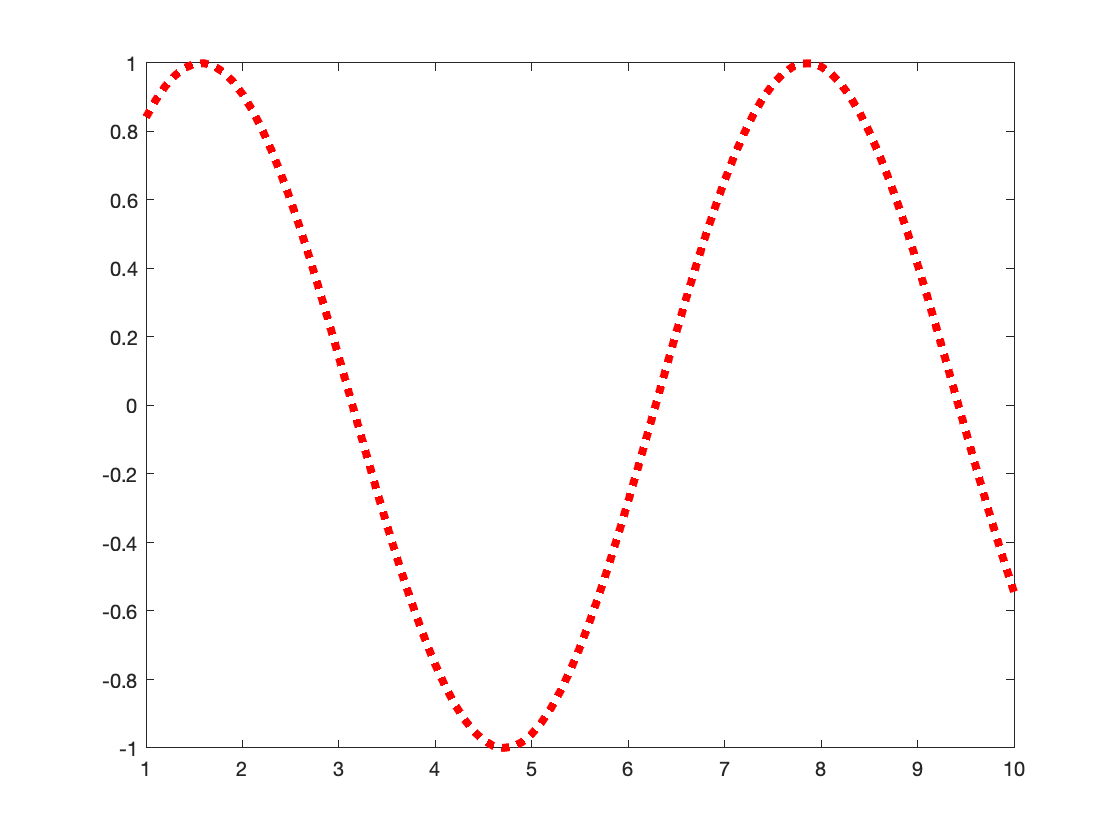

plot_object = plot(1:0.1:10, sin(1:0.1:10), 'Color', 'Red', 'LineStyle',":","MarkerEdgeColor","none",'LineWidth',4);

drawnow

Vast majority of subtle visual changes to these objects are done through keyword arguments.

### Toggling options after already having made a plot

After objects have been made, you can screw with their keyword values still, with `set()`. And you can see what properties they have that you could toggle with `get()`.

get(plot_object)

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [1 0 0]
             ColorMode: 'manual'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: ':'
         LineStyleMode: 'manual'
             LineWidth: 4
                Marker: 'none'
       MarkerEdgeColor: 'none'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×91 uint64]
            MarkerMode: 'auto'
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Se

All of those on the left hand side are posssible keyword properties of the object that you can set with `set(), e.g.`

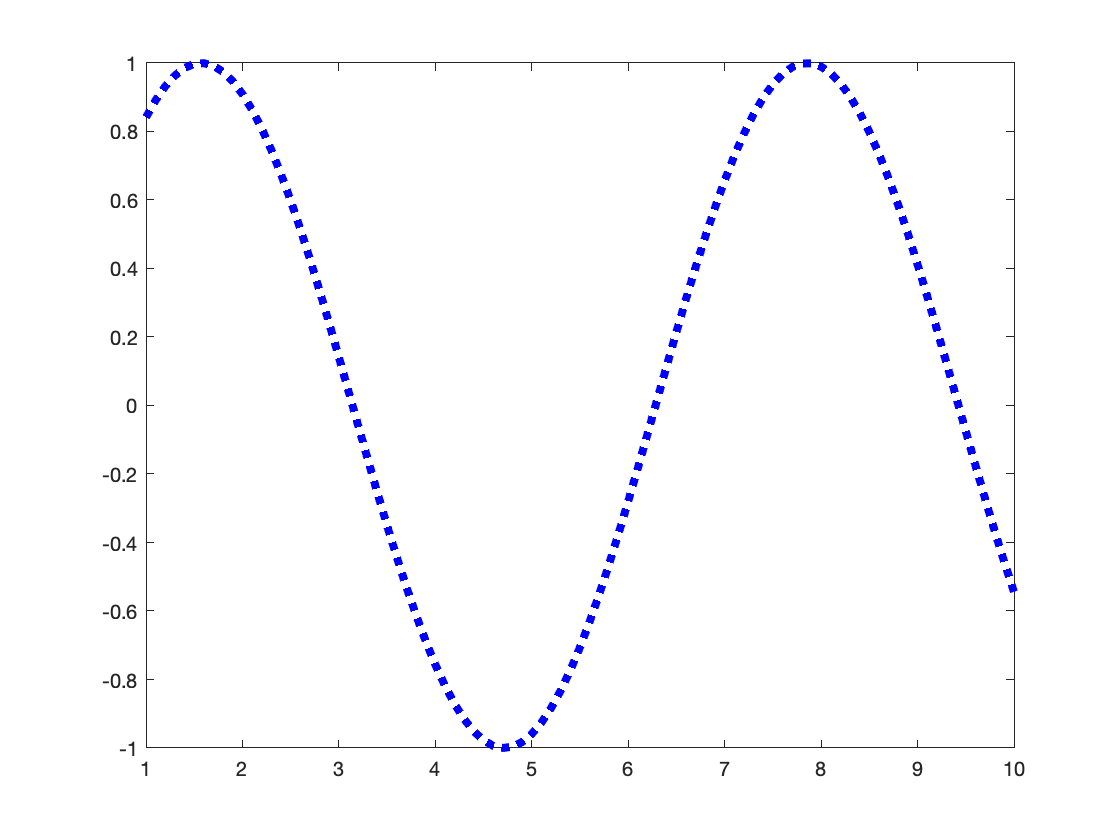

set([plot_object], 'Color', 'blue') % notice it just flips the color of the line object I already drew. not a new object.

You can set multiple keyword-value pairs at a time!

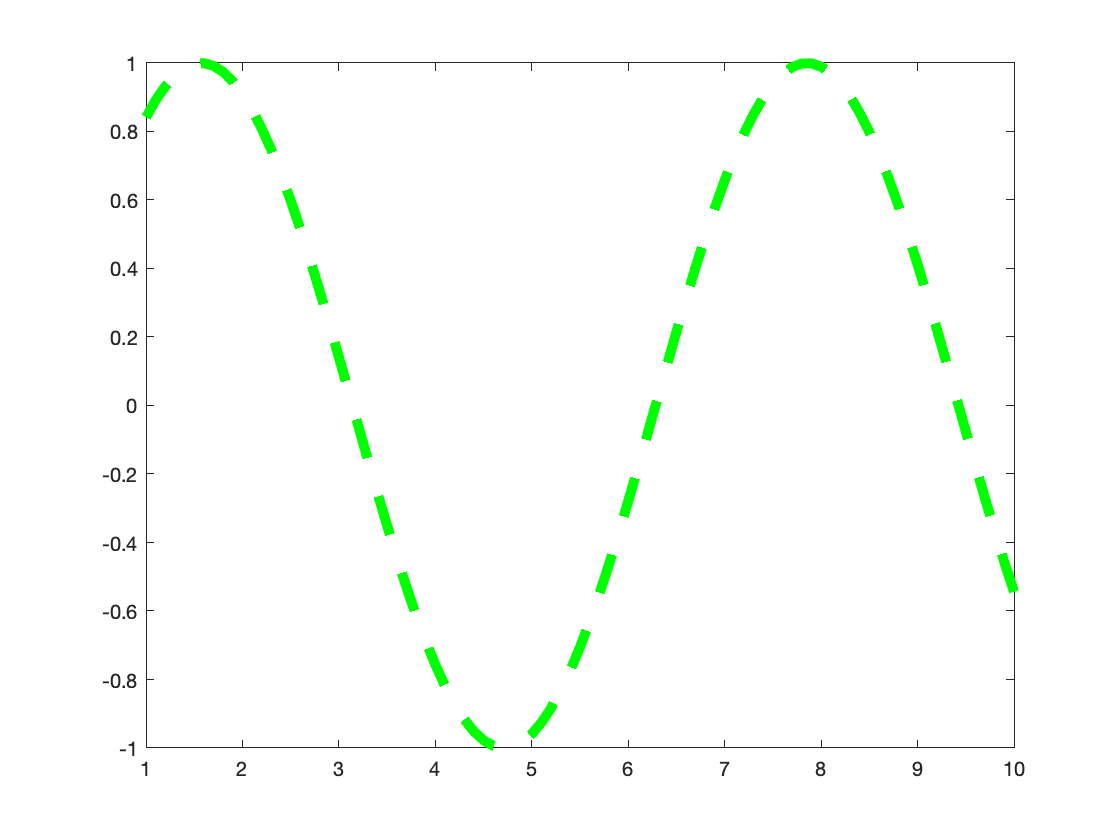

set(plot_object, 'linestyle',"--",'color','green','LineWidth',5,'Marker','o','MarkerSize',20)

So that `plot_object` lives inide an axis, and although I've not made a variable for an axis when I created the figure object (you could at the time of creation), I can still get that axis object and `set()` it. 

The axis object of the very last graphics call is gotten with `gca(), which stands for get current axis. `

ax=gca

ax =   Axes with properties:

             XLim: [1 10]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


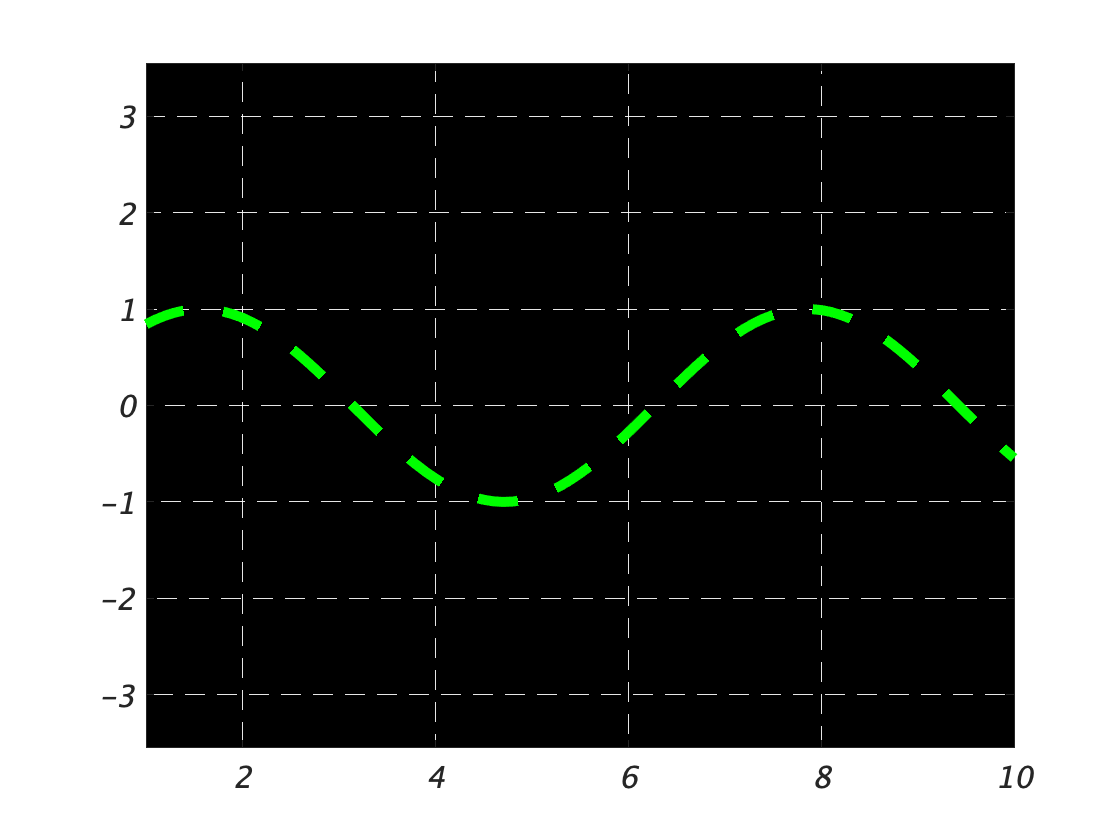

grid on
set(ax, "BoxStyle", "full", "FontSize", 15, "GridColor", 'white', "Color", "black", ...
    "GridLineStyle","--", 'GridAlpha', 0.9, 'FontName', 'RobotoMono', ...
    'FontSmoothing', 'on', 'FontAngle', "italic")
axis equal

As hinted with the axis example. The set/get also works writ large across many axis and figure objects, to control style.

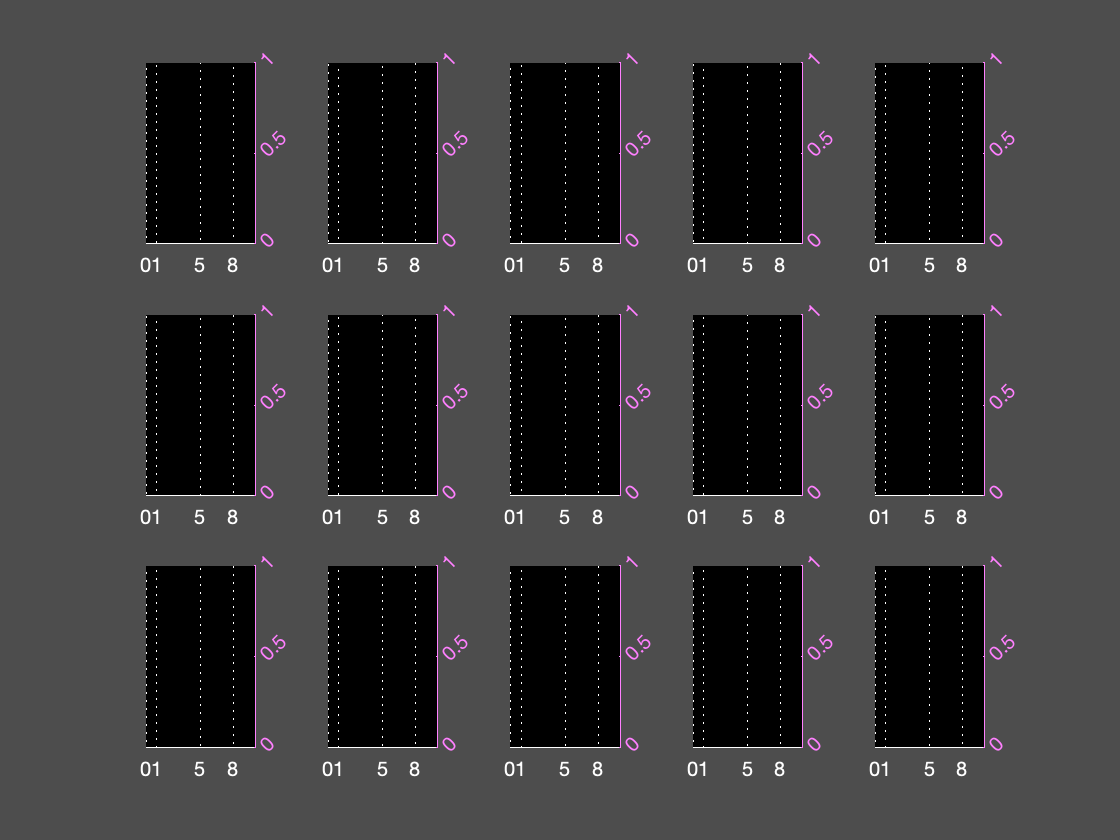

fig = figure;
for iAx = 1:(3*5)
    ax=subplot(3,5,iAx);
    set(ax, ...
        'XColor', 'white', ...
        'YColor', [1,1/2,1], ...
        'YAxisLocation', 'right', ...
        'YTickLabelRotation', 45,...
        'Color','black',...
        'XGrid','on',...
        'GridAlpha',1, ...
        'GridLineStyle',':',...
        'xlim',[0, 10],...
        'xtick', [0 1 5 8])
end
set(fig, 'Color',[0.3,0.3,0.3])

And these tricks will object be mixed with changing properties of the canvas objects to get the look you desire.

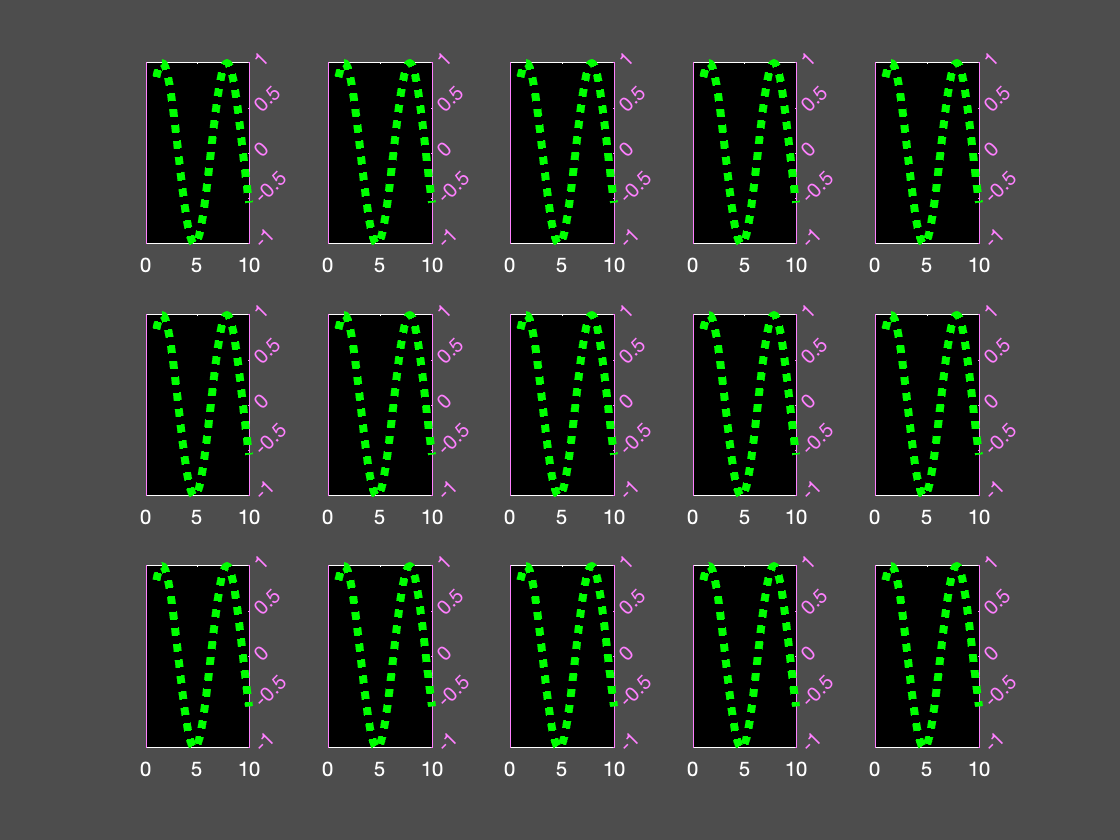

fig = figure;
for iAx = 1:(3*5)
    ax=subplot(3,5,iAx);
    plot_line_thing = ...
        plot(1:0.1:10, sin(1:0.1:10), ...
        'Color', 'Green', ...
        'LineStyle',":", ...
        "MarkerEdgeColor","none", ...
        'LineWidth',4);
    set(ax, ...
        'XColor', 'white', ...
        'YColor', [1,1/2,1], ...
        'YAxisLocation', 'right', ...
        'YTickLabelRotation', 45,...
        'Color','black')
end
set(fig, 'Color',[0.3,0.3,0.3])

## Learning on the job

This the most fundamental skill. Majority of matlab programmers are self-taught. But it's not easy to self-teach without knowing tricks of the trade to absorbing plots you've never seen. 

### Let's see an example

A scenario where I was exposed to a new plot method Matlab released that I've never seen. How did I figure out how to use it?

### Another critical way to learn: exploring the graphical objects

To review before we go any further, there are some fundamental ways to look at graphical objects and see their guts, their internals. Most good programmers will just naturally try to peel open these objects and look at the names of properties and fiddle with them. 

- get() : get properties that can be changed in matlab graphical objects, and the values they are currently set to

- properties() : print properties of most matlab objects

- methods() : print methods of most matlab objects

- open(): open a graphical object in a gui and look at change properties (only for command-line exploration, not for scripts/functions!)

## Supplementary resources

- [https://www.youtube.com/watch?v=CBeUFpwKrLY&list=PLDcmCgguL9ryT4Eg1GvWrygRz-nIWg2U8&index=21&t=0s](https://www.youtube.com/watch?v=CBeUFpwKrLY&list=PLDcmCgguL9ryT4Eg1GvWrygRz-nIWg2U8&index=21&t=0s)

- [https://www.youtube.com/watch?v=-wJAPLimOu4&list=PLDcmCgguL9ryT4Eg1GvWrygRz-nIWg2U8&index=21](https://www.youtube.com/watch?v=-wJAPLimOu4&list=PLDcmCgguL9ryT4Eg1GvWrygRz-nIWg2U8&index=21)

## Exercises: Figure anatomy

Give **two commands** that can create (or modfy) each of the properties above (except spines/legend)..Use minimally two keyword-value pairs each time. Describe what the parameters take. Use different command root names if possible:

Example `plot(x,y,'Marker','.','MarkerFaceColor','Black','Color','black','LineStyle','none')` and `scatter(x,y,'MarkerEdgeColor','Red','LineWidth',2)` can both generate points of points alone without lines.

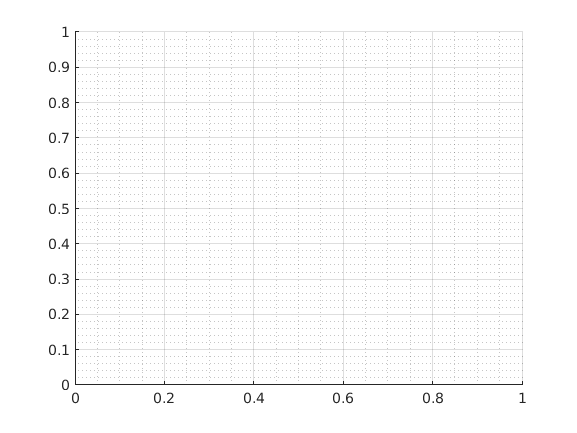

figure(8)
grid on
grid("minor")

grid off
x = [1:6];
y = [1:4];
[X,Y] = meshgrid(x,y);

## Excercises: Code commenting

(Adapted from "Neural Data Science" by Wallisch)

tenSpikeTrains = [...
    0,0,0,0,0,0,0,0,0,1,0,1,0,1,0,0,0,1,0,0,0; ...
    0,0,0,0,0,0,0,0,1,1,0,0,0,1,0,0,0,1,0,0,0;...
    0,1,0,0,0,0,0,0,0,0,1,0,0,1,0,0,0,0,0,1,0;...
    0,0,0,0,0,0,0,0,1,1,0,1,0,0,0,0,0,0,1,0,0;...
    0,0,0,0,0,0,0,0,0,1,0,0,1,0,0,0,0,0,0,0,0;...
    0,0,0,0,0,0,0,0,0,0,1,1,0,0,0,1,0,0,0,1,0;...
    0,0,0,0,0,0,0,0,1,1,1,0,0,1,1,0,0,1,1,0,0;...
    1,0,0,0,0,0,0,0,0,0,1,1,0,0,0,0,1,0,0,0,0;...
    0,0,0,0,0,0,0,0,1,1,0,0,1,1,0,0,1,1,0,0,0;...
    0,0,0,0,0,0,1,0,0,1,0,1,0,0,0,0,0,1,1,0,0];
load('tenIntensities.mat')

Error using load
Unable to read file 'tenIntensities.mat'. No such file or directory.

Throughout this excercise, refactor non-descriptive variable names like `a` / `b` / `A1` / `jj` into descriptive variable names. This will clarify what the code does.

### Problem 1

What does each line in this code box do? If it's a plotting function, what is the function of each positional and keyword argument?

figure
%plotting the spike probability by taking the sum of each row vector
% in the spike train, corresponding to # of spikes in that spike train
% then dividing by the number of bins
% and plot them in possible 21 places
% with a line that streches horizontally through x-axis at y = 0.5
% dashed and black
bar(0:20, sum(tenSpikeTrains)./ size(tenSpikeTrains,1) );
line(xlim,[0.5 0.5], ...
    'linestyle','--','color','k')

### Problem 2

What does each line in this code box do? If it's a plotting function, what is the function of each positional and keyword argument?

figure
% add a green rectangle from (5,0) to (9,11)
rectangle('Position',[5,0,9,11],'FaceColor',[0.7 1 0.7],'linestyle','none')
xlim([-0.5 20])
ylim([0 1])
hold on
bar(0:20,sum(tenSpikeTrains)./size(tenSpikeTrains,1));
line(xlim,[0.5 0.5],'linestyle','--','color','k')
title('spike probability given 10 stimulus trials')
xlabel('time (in milliseconds)')
ylabel('probability of spiking at this time')

### Problem 3

Write in a comment what every line of this does and what every parameter on that line (who isn't a positional parameter) is doing. If you don't know, look up the function called in that line. (Deliberately not making the variables well-named here.)

load('Shared/Tutorial/tenIntensities.mat')
figure
a = [1:2:20]; % making subplots
b = [2:2:20]; % making another group of subplots
for ii = 1:size(A2,1)
    subplot(10,2,a(ii))
        if ii == 1
            title('raster plot for each intensity')
        end
    rectangle('Position',[5,0,9,11],'FaceColor',[1-(0.1.*ii) 1 1-(0.1.*ii)],'linestyle','none')
    for jj = 1:10
        spikeTimes = find(A2{ii,1}(jj,:)==1)-1;
        % find the times of spiking
        line(repmat(spikeTimes,2,1),repmat([jj-0.5; jj+0.5],1,length(spikeTimes)),'color','k')
        xlim([0 20])
        ylim([0.5 10.5])
        set(gca,'xtick',[])
    end
end
%xlabel('time (in milliseconds)')
%ylabel('Trial number')
set(gca,'Layer','top')
for ii = 1:size(A2,1)
    subplot(10,2,b(ii))
    if ii == 1
        title('PSTH for each intensity')
    end
    rectangle('Position',[5,0,9,8],'FaceColor',[0.7 1 0.7],'linestyle','none')
    hold on
    x=0:length(A2{ii,1})-1;
    bar(x,sum(A2{ii,1}));
    xlim([-0.5 20])
    ylim([0 8])
    set(gca,'xtick',[])
    %xlabel('time (in milliseconds)')
    %ylabel('# spikes')
end

### Problem 4

Same as the above. 

A3  = zeros(10,100);
for ii = 1:size(A2,1)
    A3(ii,:) = (sum(A2{ii,1})./10);
end
A3(:,22:100) = [];
figure
h = pcolor(A3);
set(h,'Facecolor','interp')
set(h,'Linestyle','none')
set(gca,'YDir','reverse')
colormap('hot')
h = colorbar;
ylabel(h, 'mean spikes per time bin')
xlabel('time (in milliseconds)')
ylabel('stimulus intensity')
title('heat map of mean spiking for stimuli of varying intensity')

### Problem 5

Same as the above. 

figure
ax1 = subplot(2,2,1);
h = pcolor(A3);
set(h,'Facecolor','interp')
set(h,'Linestyle','none')
set(gca,'YDir','reverse')
colormap(ax1,'hot')
axis off
ax2 = subplot(2,2,2);
h = pcolor(A3);
set(h,'Linestyle','none')
set(gca,'YDir','reverse')
colormap(ax2,'bone')
axis off
ax3 = subplot(2,2,3);
h = pcolor(A3);
set(h,'Facecolor','interp')
set(h,'Linestyle','none')
set(gca,'YDir','reverse')
colormap(ax3,'jet')
axis off
ax4 = subplot(2,2,4);
h = pcolor(A3);
set(h,'Linestyle','none')
set(gca,'YDir','reverse')
colormap(ax4,'winter')
axis off

cdata = [45 60 32; 43 54 76; 32 94 68; 23 95 58];
xvalues = {'Small','Medium','Large'};
yvalues = {'Green','Red','Blue','Gray'};
h = heatmap(xvalues,yvalues,cdata);

h.Title = 'T-Shirt Orders';
h.XLabel = 'Sizes';
h.YLabel = 'Colors';

figure;
cdata = [45 60 32; 43 54 76; 32 94 68; 23 95 58];
size(cdata)
[X,Y] = meshgrid(1:3, 1:4)
pcolor(X,Y,cdata)
xticks([1:3])